# ECE 5553 Final Project

Brian Lesko

Kevin lastname

Ovee Dankithcar

# Contents

- longitudinal dynamics parameters

- longitudinal dynamics with nonlinear tire model (dugoff)

- estimation of nonlinear system with LTI system 

- lateral dynamics parameters

- lateral dynamics simulation with the bicycle model, linear and nonlinear comparison

# Longitudinal dynamics parameters

Deriving more accurate parameters by modifying parameters of a sedan, used in a previous project, below:

clc; clear; close all;

% longitudinal dynamics parameters for a sedan
    % M=2000; % Mass of the vehicle[Kg]
    % eta_t=0.9; % Transmission Efficiency
    % lambda_t=1.0; % Gear Ratio
    % lambda_f=4.1; % Final Drive Ratio
    % I_w=1; % Inertia of the Wheel[kgm2]
    % R_w=0.3; % Wheel Radius[m]
    % Meq=0.1*M; % Equivalent Mass Factor
    % C_d=0.29; % Drag coefficient
    % rho=1.225; % Air density[kg/m3]
    % A_f=2.8;% Frontal area	[m2]
    % g=9.81;% [N/m2]
    % C_rr=0.015;%Rolling resistance coefficient
    % C_x=3e5; %Longitudinal Stiffness[N]
    % C_alpha = 1.5e5; % Cornering Stiffness for 1 tire [N/rad]
    % L=2.85;% Wheelbase[m]
    % l_f=1.3;% Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    % l_r=1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    % C_s=1.5e5;% Cornering Stiffness of Front and Rear Tires [N/rad]
    % I_z=3700;% Inertia moment around z axis J or Iz [kg/m2]
    % mu=0.7; % Road friction coefficient

% for the shuttle
    M=3500; % Mass of the vehicle[Kg] based on Tesla Model X size and weight, the shuttle will be 2k kg heavier
    eta_t=0.8; % Transmission Efficiency, less efficient than a sedan
    lambda_t=1.0; % Gear Ratio, the same as the sedan 
    lambda_f=4; % Final Drive Ratio, same as the sedan
    I_w=1; % Inertia of the Wheel[kgm2], same as the sedan
    R_w=0.3; % Wheel Radius[m], same as the sedan
    Meq=0.1*M; % Equivalent Mass Factor, same as the sedan
    C_d=0.4; % Drag coefficient, Worse drag than the sedan
    rho=1.225; % Air density[kg/m3], same as the sedan (obviously)
    A_f=6;% Frontal area [m2], more frontal area than the sedan 
    g=9.81;% [N/m2], same as the sedan
    C_rr=0.015;%Rolling resistance coefficient, same as the sedan

    C_x=3e5; %Longitudinal Stiffness[N], same as the sedan
    C_alpha = 1.5e5; % Cornering Stiffness for 1 tire [N/rad], same as the sedan

    L=4.75;% Wheelbase[m], longer by 2 meters than the sedan 
    l_f=2.25;% Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=2.5;% Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_s=1.5e5;% Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=4000;% Inertia moment around z axis J or Iz [kg/m2] Higher
    mu=0.7; % Road friction coefficient same 

[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();


# Longitudinal Dynamics via Duggoff model 

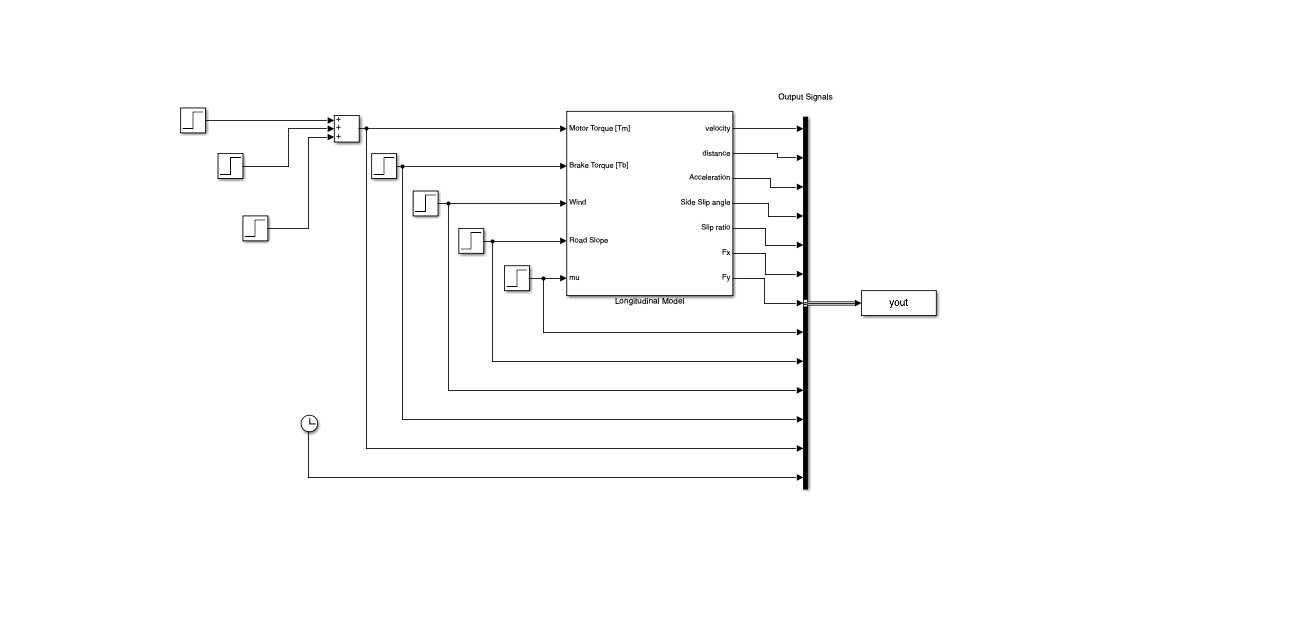

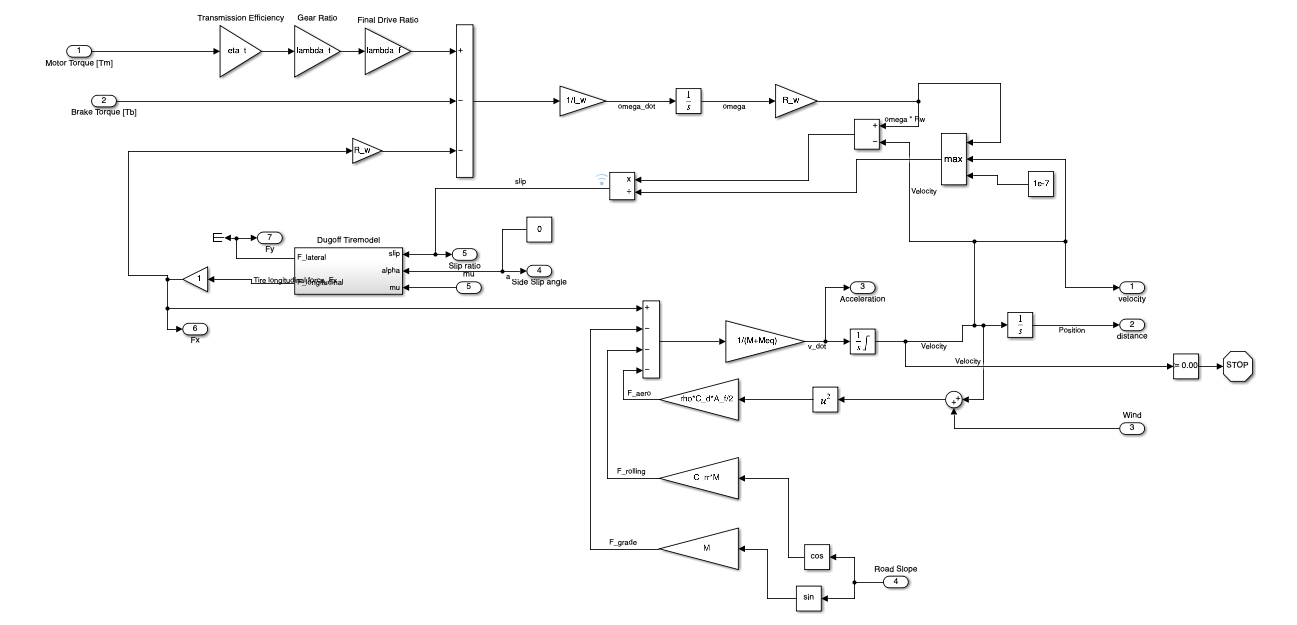

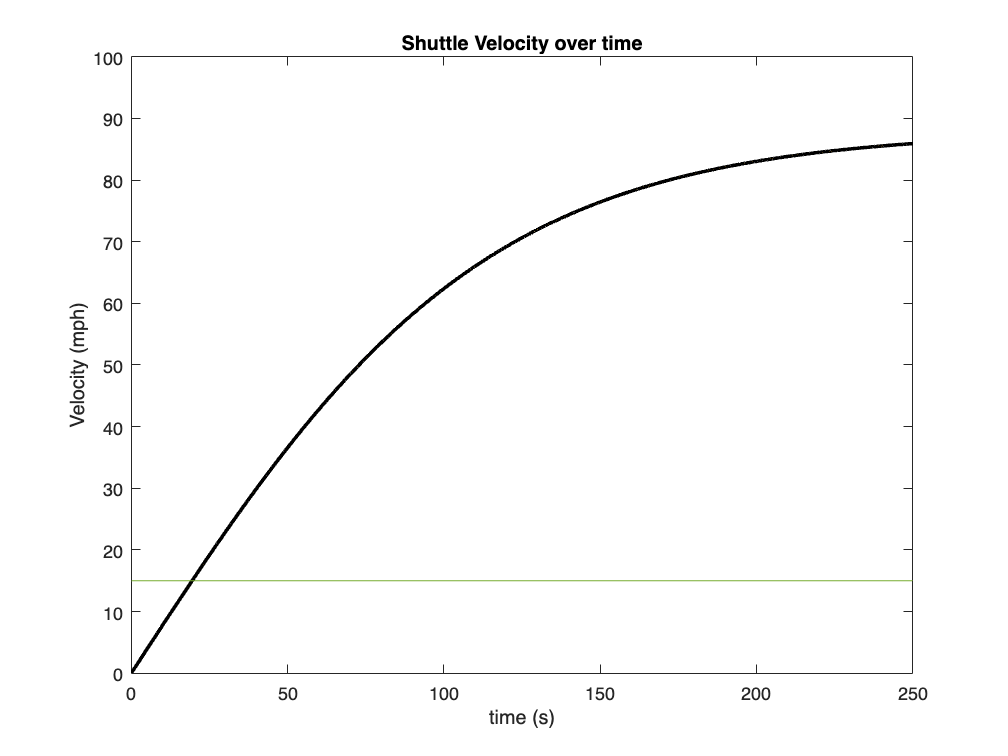

% unchanging Sim parameters for pure acceleration
[motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero();
[M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters();

motorStart = 65;
addpath("Simulink_Models/")
sim("longitudinal_modelV2.slx")
ynames = ["V","X","A","Side Slip Angle","Slip Ratio","Tire force Fx","Tire Force Fy","Motor Torque","Brake Torque","Wind Force","Road Slope","Mu","time"];
sim1 = yout;
time1 = sim1(:,length(ynames));
plot(time1,2.23694*sim1(:,1),'k','Linewidth',2), ylabel('Velocity (mph)'), xlabel('time (s)'), title('Shuttle Velocity over time'), hold on
axis([0 250 0 100])
% horizontal line
line_x = linspace(0,250,4); line_y = 15 * ones(1,length(line_x)); plot(line_x,line_y)

The longitudinal dynamics model used to make this curve originates from the duggoff model which uses the parameters chosen in the previous section. With the desired cruising velocity of 15 mph, the shuttle can reach this speed after ~ 20 seconds, which is reasonable for the low speed application of this shuttle. Overally, this is likely a reasonable velocity time curve for standard use. It is however built off the nonlinear duggoff tire model and is higher fidelity than needed in ongoing steps of the project. Therefor, in the next sectioon this curve's transfer function will be described and approximated using a simple linear system. 

# LTI System Approximation 

The system that creates the transfer function above can be described as a linear single input single output transfer function with Velocity as the output and Motor torque as the input. Therefor, the simulated transfer function can be displayed by plotting the simulation Velocity values divided by the motor torque, which we chose as constant in the last section. 

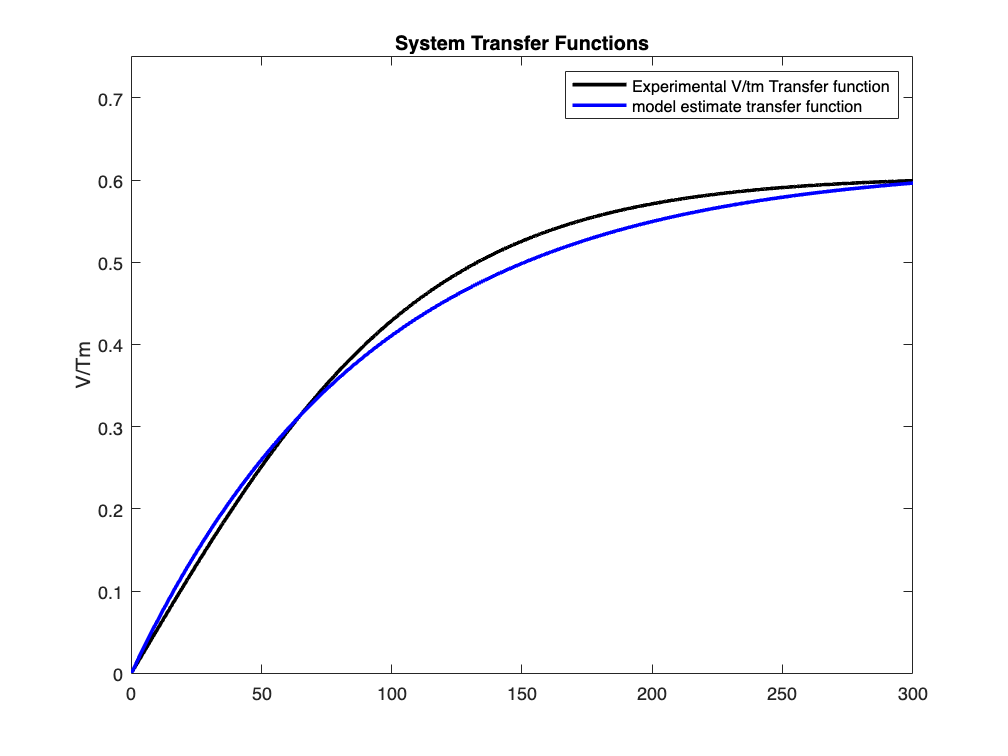

motor_torque = motorStart;
velocity = sim1(:,1);

figure()
plot(time1,velocity/motor_torque,'k','Linewidth',2), ylabel('System'), xlabel(''), title('Shuttle Velocity / Motor Torque'), hold on

K = 0.62;
T = 92;

s = tf('s');
V_tf = K/ (T*s + 1);

[h,g] = step(V_tf);
plot(g, squeeze(h), 'b','LineWidth',2)

legend('Experimental V/tm Transfer function','model estimate transfer function')
title('System Transfer Functions')
ylabel('V/Tm')
axis([0 300 0 .75])

The LTI system approximates the duggoff model around our motor torque of interest of 65 Nm, lets reproduce the velocity time curve from this LTI system and compare it to the simulated duggoff model

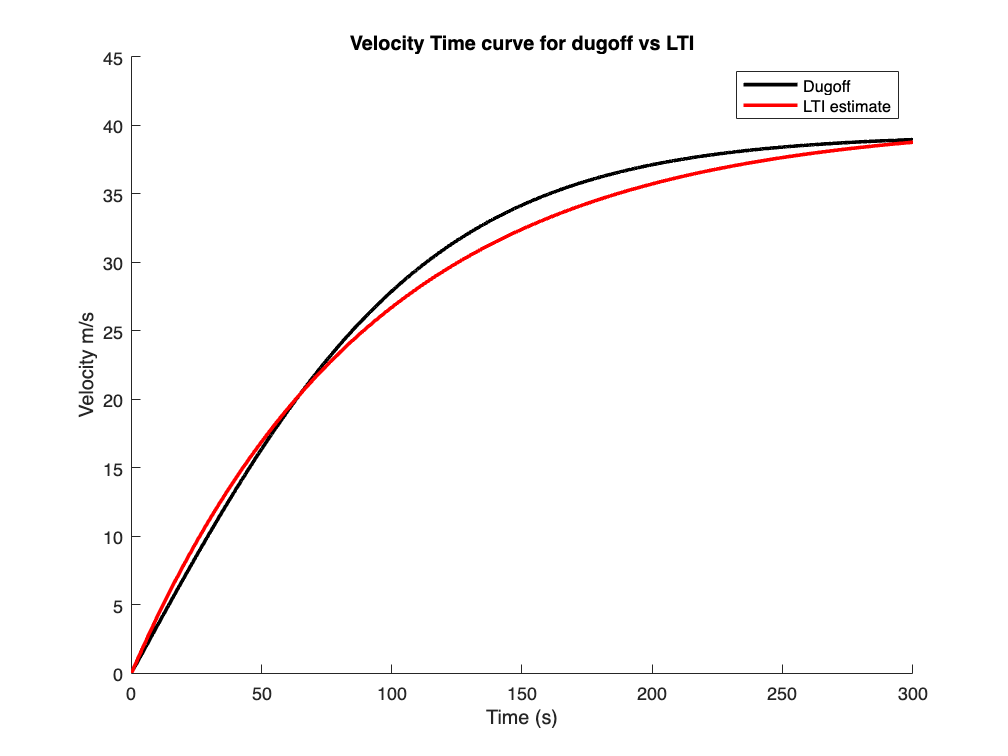

figure(), hold on
plot(time1,sim1(:,1),'k','Linewidth',2)
plot(g,h*motor_torque,'Linewidth',2,'Color',[1 0 0])
xlabel('Time (s)'), ylabel('Velocity m/s'), title('Velocity Time curve for dugoff vs LTI'), legend('Dugoff','LTI estimate'), axis([0 300 0 45])

This curve is just a scaled version of the previous one. 

# Lateral Dynamics Parameters

% These Lateral parameters have overlap with the longitudinal values
% chosen, and have been set to match

    % L=4.75; % Distance between the axles [m], matched with first set
    % g=9.81; %
    % Lr = 2.5;% Distance from the center of gravity of the vehicle (CG) to the rear axle, matched with first set
    % Lf = 2.25; % Distance from the center of gravity of the vehicle (CG) to the front axle, matched with first set
    % Cf = 1.5e5; % Cornering Stiffness of Front Tires x2, matched with first set
    % Cr = 1.5e5; % Cornering Stiffness of Rear Tires x2, matched with first set
    % Cs = 1.5e5; % Cornering Stiffness, matched with first set
    % m = 3500; %Mass of the vehicle [kg], matched with first set
    % J = 4000; %Yaw moment of Inertia, matched with first set
    % mu = 0.7; %Dry coefficient of Friction, matched with first set
    % R = 0.3; % Wheel radius, matched with first set
    % Vref = 20; % Constant vehicle velocity.
    % alphaf = 0.1; % Steering wheel angle rad/sec
    % 
    % %Linear Parameters Calculation 
    % a11 = -(Cr+Cf)/(mVref);
    % a12 = -1-((CfLf-CrLr)/(mVref^2));
    % a21 = (LrCr-LfCf)/J;
    % a22 = -((CfLf^2)+(CrLr^2))/(VrefJ);
    % b11 = Cf/(mVref);
    % b12 = Cr/(mVref); %delta_r parameter
    % b21 = CfLf/J;
    % b22 = Cr*Lr/J; %delta_r parameter
    % e2 = 1/J; % For yaw moment term 

[L,g,Lr,Lf,Cf,Cr,Cs,m,J,mu,R,Vref,alphaf,a11,a12,a21,a22,b11,b12,b21,b22,e2] = getLateralParameters();
Vref = 6.7;

# Lateral Dynamics Simulation

Lets use the lateral model comparison simulink from an earlier project

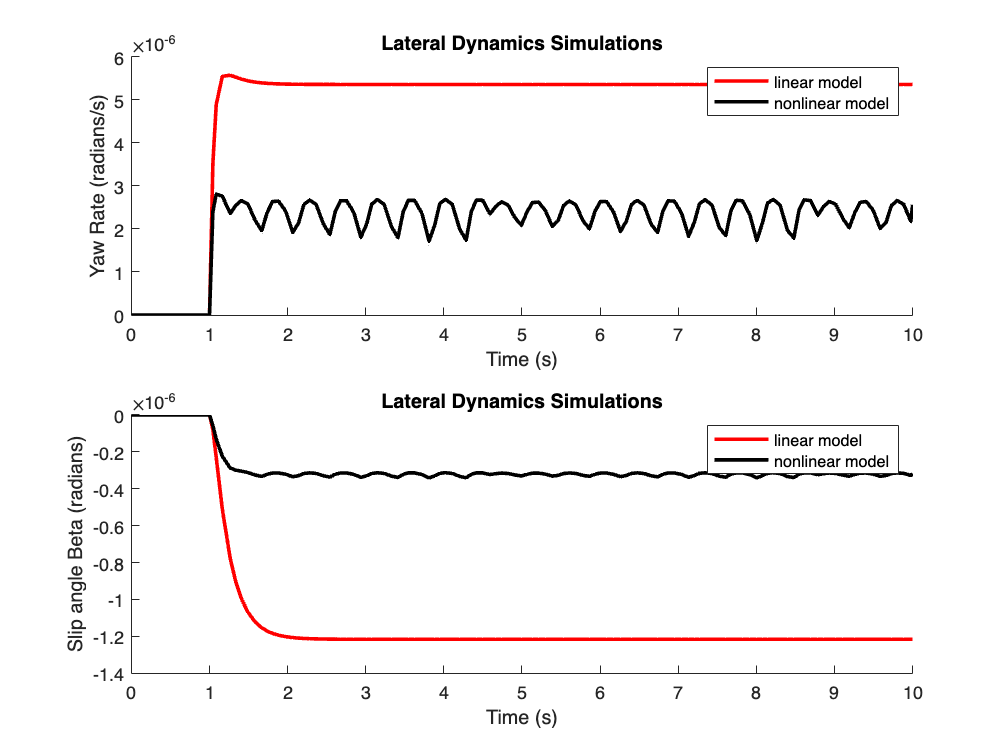

sim('lateral_models')
figure
subplot(2,1,1), hold on
plot(time,yawRateLin,'r','linewidth',2)
plot(time,yawRateNonLin,'k','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Yaw Rate (radians/s)')
subplot(2,1,2), hold on
plot(time,betaLin,'r','linewidth',2)
plot(time,betaNonLin,'k','linewidth',2)
legend('linear model','nonlinear model'), title('Lateral Dynamics Simulations'),xlabel('Time (s)'), ylabel('Slip angle Beta (radians)')

These figures showcase the difference between the bicycle model with linear tires vs nonlinear dugoff tire models. The linear tires overestimate both the yaw rate and side slip angle, but resemble the same shape. 

# Path Following model 

Using the bicycle model with linear tires, the same as the red curves in the previous section

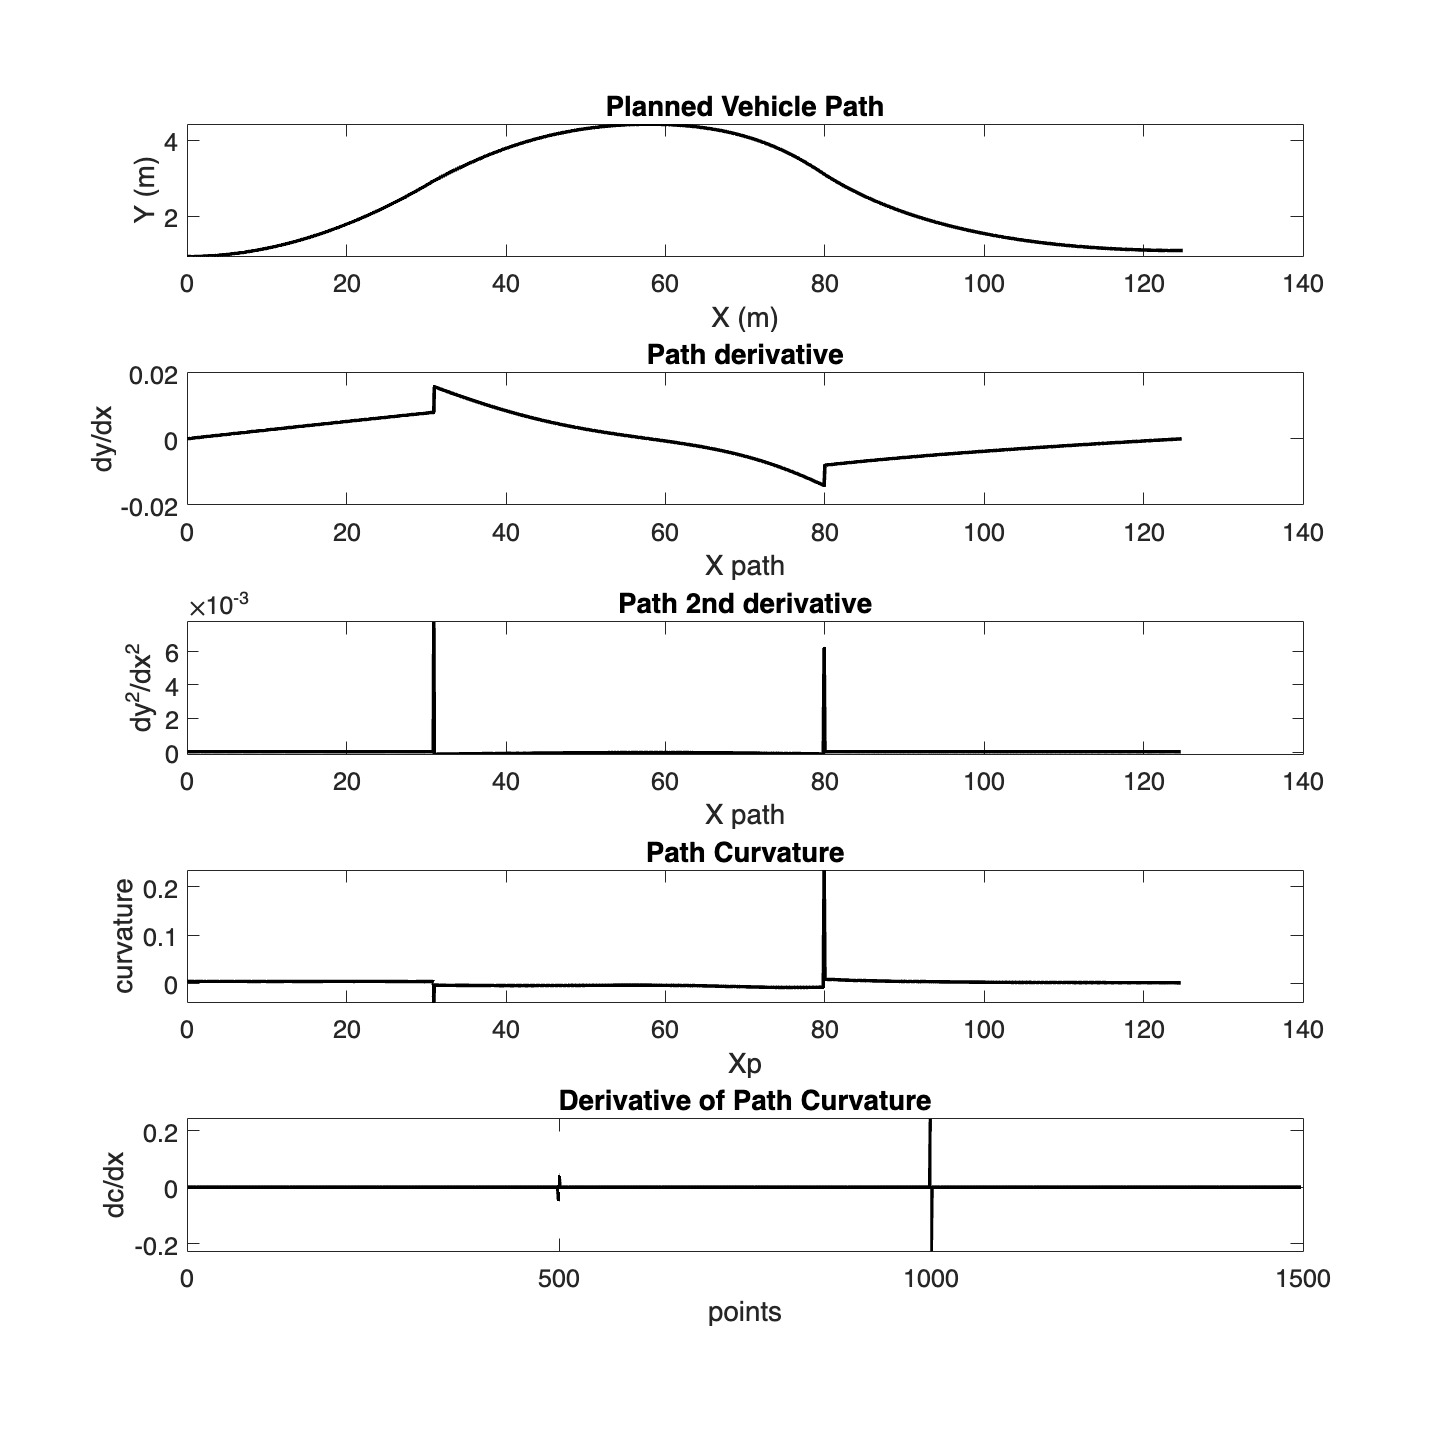

[L,g,Lr,Lf,Cf,Cr,Cs,m,J,mu,R,V,alphaf,a11,a12,a21,a22,b11,b12,b21,b22,e2] = getLateralParameters();
ls = 2; % m
V = 6.7; % m/s
%%%%State Space Representation needs to be added to the existing parameters
    A_matrix = [a11 a12 0 0; a21 a22 0 0; 0 1 0 0; V ls V 0];
    B_matrix = [b11 0; b21 0; 0 -V; 0 -ls*V];
    C_matrix = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %Output is beta, r and ey
    D_matrix = [0 0; 0 0; 0 0; 0 0];

% Controller parameters
P = -1;
I = -4.5;
D = 0.0113;
N = 200;

% Path Generation
[Xp,Yp] = getC0Path();
plotPathQuality(Xp,Yp)

% Variables Needed for simulink model 
path_curvatures = getPathCurvature(Xp,Yp); 
cumulative_distances = getCumulativeDistances(Xp,Yp); % the simulink uses this variable in a lookup table 
dis_vec = cumulative_distances(1:end-1); % the model uses only n-2 entries in its lookup table because curvature loses two entries

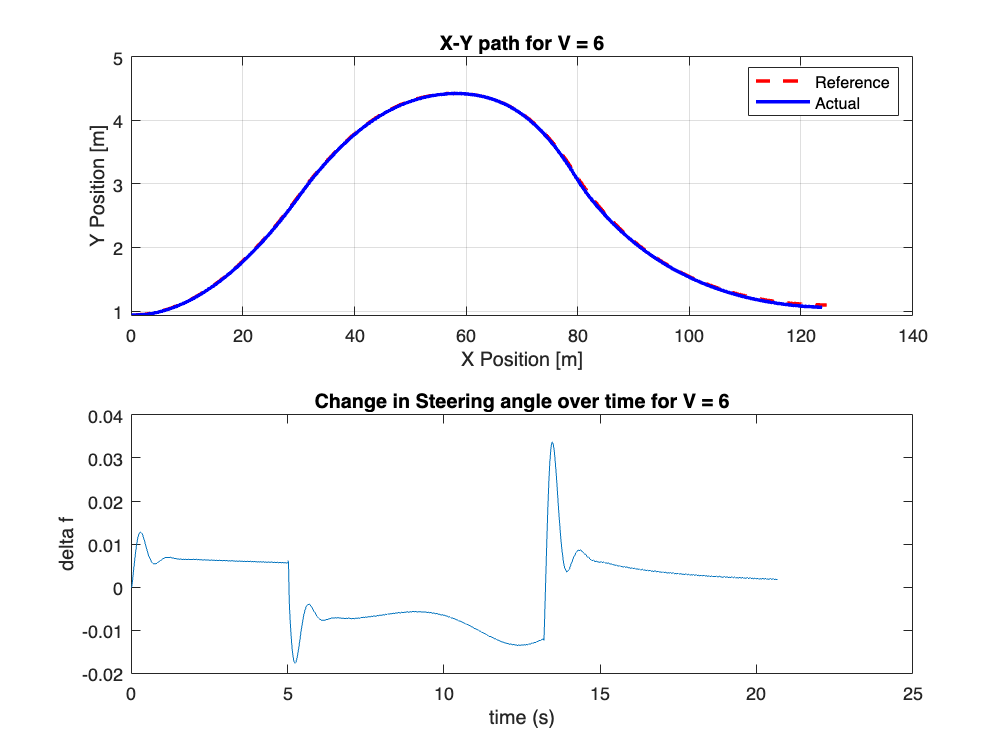

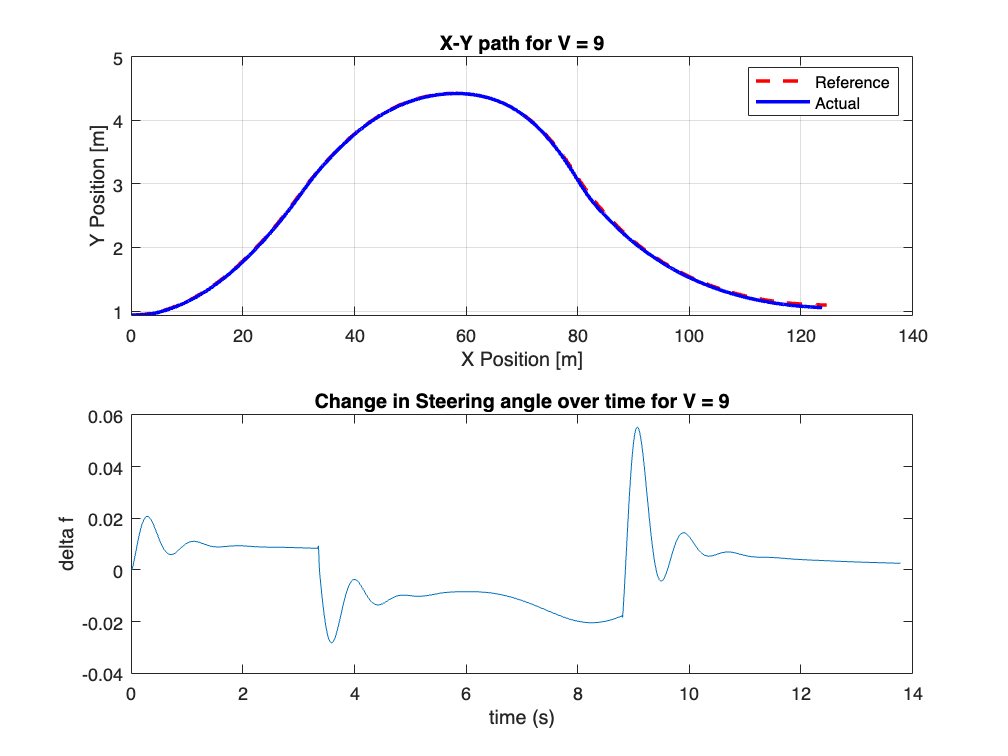

%%Operating condition
ls = 2; %Preview Distance [m]

loop = 1;
Velocities = [6.7,9];
n = length(Velocities);
for V = Velocities
    figure(), hold off
    
    [A_matrix, B_matrix, C_matrix, D_matrix] = changeModel(V,ls);
    sim('PathFollowingModel');

    % actual vs refrence path
    subplot(2,1,1), plot(X_ref,Y_ref,'r--','Linewidth',2); hold on; grid on; plot(X_actual,Y_actual,'b','Linewidth',2); grid on; hold off
    legend('Reference','Actual'),xlabel('X Position [m]'),ylabel('Y Position [m]'),title(['X-Y path for V = ', num2str(V)]);

    % plot Steering angle change 
    subplot(2,1,2), plot(time,delta_f_out)
    xlabel('time (s)'), ylabel('delta f'), title(['Change in Steering angle over time for V = ', num2str(V)]);

    loop = loop + 1;
end 

# Functions

#### Fetch longitudinal parameters

function [M, eta_t, lambda_t, lambda_f, I_w, R_w, Meq, C_d, rho, A_f, g, C_rr, C_x, C_alpha,L, l_f, l_r, C_s, I_z, mu] = getLogitudinalParameters()
    M=2000; % Mass of the vehicle[Kg]
    eta_t=0.9; % Transmission Efficiency
    lambda_t=1.0; % Gear Ratio
    lambda_f=4.1; % Final Drive Ratio
    I_w=1; % Inertia of the Wheel[kgm2]
    R_w=0.3; % Wheel Radius[m]
    Meq=0.1*M; % Equivalent Mass Factor
    C_d=0.29; % Drag coefficient
    rho=1.225; % Air density[kg/m3]
    A_f=2.8;% Frontal area	[m2]
    g=9.81;% [N/m2]
    C_rr=0.015;%Rolling resistance coefficient
    C_x=3e5; %Longitudinal Stiffness[N]
    C_alpha = 1.5e5; % Cornering Stiffness for 1 tire [N/rad]
    L=2.85;% Wheelbase[m]
    l_f=1.3;% Distance from the center of gravity of the vehicle (CG) to the front axle [m]
    l_r=1.55;% Distance from the center of gravity of the vehicle (CG) to the rear axle [m]
    C_s=1.5e5;% Cornering Stiffness of Front and Rear Tires [N/rad]
    I_z=3700;% Inertia moment around z axis J or Iz [kg/m2]
    mu=0.7; % Road friction coefficient
end 
function [motorStart,motorStartTime,motorIncrease,motorIncreaseTime,motorDecrease,motorDecreaseTime,brakeTime,breakStrength,headWindTime,headWind,roadSlopeTime,roadSlope] = setLongitudinalInputsToZero()  
    motorStart = 0; motorStartTime = 0;
    motorIncrease = 0;motorIncreaseTime = 0; 
    motorDecrease = 0;motorDecreaseTime = 0;
    brakeTime = 0;breakStrength = 0;
    headWindTime = 0;headWind = 0;
    roadSlopeTime = 0;roadSlope = 0;
end 

#### Sample a vector evenly to make it length b

function y = sampVec(x, b)
    % x: input vector
    % b: length of output vector
    a = length(x);
    y = linspace(1, a, b)';
    y = round(y);
    y = x(y);
end

#### Fetch stored Lateral Parameters

function [L,g,Lr,Lf,Cf,Cr,Cs,m,J,mu,R,Vref,alphaf,a11,a12,a21,a22,b11,b12,b21,b22,e2] = getLateralParameters()
    L=4.75; % Distance between the axles [m], matched with first set
    g=9.81; %
    Lr = 2.5;% Distance from the center of gravity of the vehicle (CG) to the rear axle, matched with first set
    Lf = 2.25; % Distance from the center of gravity of the vehicle (CG) to the front axle, matched with first set
    Cf = 1.5e5; % Cornering Stiffness of Front Tires x2, matched with first set
    Cr = 1.5e5; % Cornering Stiffness of Rear Tires x2, matched with first set
    Cs = 1.5e5; % Cornering Stiffness, matched with first set
    m = 3500; %Mass of the vehicle [kg], matched with first set
    J = 4000; %Yaw moment of Inertia, matched with first set
    mu = 0.7; %Dry coefficient of Friction, matched with first set
    R = 0.3; % Wheel radius, matched with first set
    Vref = 20; % Constant vehicle velocity.
    alphaf = 0.1; % Steering wheel angle rad/sec
    
    %Linear Parameters Calculation
    a11 = -(Cr+Cf)/(m*Vref);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
    b11 = Cf/(m*Vref);
    b12 = Cr/(m*Vref); %delta_r parameter
    b21 = Cf*Lf/J;
    b22 = Cr*Lr/J; %delta_r parameter
    
    e2 = 1/J; % For yaw moment term
end 
function [A_matrix, B_matrix, C_matrix, D_matrix] = changeModel(V,ls) 
    L=4.75; % Distance between the axles [m], matched with first set
    g=9.81; %
    Lr = 2.5;% Distance from the center of gravity of the vehicle (CG) to the rear axle, matched with first set
    Lf = 2.25; % Distance from the center of gravity of the vehicle (CG) to the front axle, matched with first set
    Cf = 1.5e5; % Cornering Stiffness of Front Tires x2, matched with first set
    Cr = 1.5e5; % Cornering Stiffness of Rear Tires x2, matched with first set
    Cs = 1.5e5; % Cornering Stiffness, matched with first set
    m = 3500; %Mass of the vehicle [kg], matched with first set
    J = 4000; %Yaw moment of Inertia, matched with first set
    mu = 0.7; %Dry coefficient of Friction, matched with first set
    R = 0.3; % Wheel radius, matched with first set
    Vref = 20; % Constant vehicle velocity.
    alphaf = 0.1; % Steering wheel angle rad/sec
    
    %Linear Parameters Calculation
    a11 = -(Cr+Cf)/(m*Vref);
    a12 = -1-((Cf*Lf-Cr*Lr)/(m*Vref^2));
    a21 = (Lr*Cr-Lf*Cf)/J;
    a22 = -((Cf*Lf^2)+(Cr*Lr^2))/(Vref*J);
    b11 = Cf/(m*Vref);
    b12 = Cr/(m*Vref); %delta_r parameter
    b21 = Cf*Lf/J;
    b22 = Cr*Lr/J; %delta_r parameter
    
    e2 = 1/J; % For yaw moment term
    
    %%%%State Space Representation
    A_matrix = [a11 a12 0 0; a21 a22 0 0; 0 1 0 0; V ls V 0];
    B_matrix = [b11 0; b21 0; 0 -V; 0 -ls*V];
    C_matrix = [1 0 0 0; 0 1 0 0; 0 0 1 0; 0 0 0 1]; %Output is beta, r and ey
    D_matrix = [0 0; 0 0; 0 0; 0 0];
end 

# Path Following Functions 

function cumulative_distances = getCumulativeDistances(Xp,Yp)
    % This function calculates the cumulative distances traveled based on Xp and Yp arrays of coordinates

    % Initialize the total distance traveled to 0
    Tot_d = 0;
    
    % Loop through all the points in the input arrays (from the first to the second to last)
    cumulative_distances = zeros(length(Xp)-1,1);
    for j = 1:length(Xp)-1
        % Calculate the Euclidean distance between the consecutive points (j and j+1)
        d(j) = sqrt((Xp(j+1)-Xp(j))^2+(Yp(j+1)-Yp(j))^2); 
        
        % Update the total distance with the calculated distance
        Tot_d = Tot_d + d(j);
        
        % Store the cumulative distance traveled so far in the output array
        cumulative_distances(j) = Tot_d;
    end
end
function path_curvatures = getPathCurvature(Xp, Yp)
    % Road Curvature Calculations

    % Input: Xp and Yp are vectors containing the X and Y coordinates of the path points
    % Output: path_curvatures is a vector containing the curvature values for each point in the path

    % Check if Xp and Yp have the same length
    if length(Xp) ~= length(Yp)
        error('Input vectors Xp and Yp must have the same length.');
    end

    % Compute the first-order differences (derivatives)
    d_Xp = diff(Xp);
    d_Yp = diff(Yp);

    % Compute the second-order differences (second derivatives)
    dd_Xp = diff(Xp, 2);
    dd_Yp = diff(Yp, 2);

    % Curvature formula given in Lecture 21, Slide 27
    % (d_Xp * dd_Yp - d_Yp * dd_Xp) / ((d_Xp^2 + d_Yp^2)^(3/2))
    path_curvatures = (d_Xp(2:end) .* dd_Yp - d_Yp(2:end) .* dd_Xp) ./ (d_Xp(2:end).^2 + d_Yp(2:end).^2).^1.5;
end
function [Xp,Yp] = getC0Path()
    %Initialize the variables
    Xp = [];
    Yp = [];
    
    %%%%%%%
    %DOUBLE LANE CHANGE MANOEUVER - ISO 3888-1
    %%%%%%%

    Veh_width = 1.57; %For a Mid-size Sedan Vehicle, width in m
    L1 = Veh_width*1.1+0.15;
    L2 = Veh_width*1.2+0.15;
    L3 = Veh_width*1.3+0.15;
    
    p = []; 
    
    %Change the points here to modify the shape of the curve.
    %If you are adding new points, make sure you modify the p & p_ub_pts array
    %points accordingly
    p_lb_pts = [0,0; 15,0; 31,2; 45,3.5; 53,3.5; 63,3.5; 70,3.5; 80,2; 95,0; 125,0;]; %Points on the curve considering 0,0 starting point and no offset L1,L2,L3
    %p_lb_pts = [0,0; 15,0; 31.25,1.95; 45,3.5; 53,3.5; 63,3.5; 70,3.5;81.75,1.95; 95,0; 125,0;]; % good path!
    %p_lb_pts = [0,0; 15,0; 31,2; 45,3.5; 53,3.5; 63,3.5; 70,3.5; 80,2; 95,0;125,0;]; %best path so far
    
    p_ub_pts = p_lb_pts;
    p = p_lb_pts;
    
    %Upper Bound
    p_ub_pts(1:3,2) = p_lb_pts(1:3,2)+(L1); %Offset of the path. upper bound
    p_ub_pts(4:7,2) = p_lb_pts(4:7,2)+(L2); %Offset of the path. upper bound
    p_ub_pts(8:10,2) = p_lb_pts(8:10,2)+(L3); %Offset of the path. upper bound
    
    %Mid-path
    p(1:3,2) = p_lb_pts(1:3,2)+(L1/2); %Offset of the path to the centre of the vehicle
    p(4:7,2) = p_lb_pts(4:7,2)+(L2/2); %Offset of the path to the centre of the vehicle
    p(8:10,2) = p_lb_pts(8:10,2)+(L3/2); %Offset of the path to the centre of the vehicle
    
    %Split the points into three bezier curves%
    
    %Beizer Curves passes through first and last points and approximates
    %through the middle points. This is the characteristic of the Beizer curve
    p1 = p(1:3,:); 
    p2 = p(3:8,:);
    p3 = p(8:10,:);
    
    
    [Xp_1,Yp_1] = bezier_curve(p1); %For first curve
    [Xp_2,Yp_2] = bezier_curve(p2); %For second curve
    [Xp_3,Yp_3] = bezier_curve(p3); %For third curve

    Xp = [Xp_1(1:end-1); Xp_2(1:end-1); Xp_3(1:end-1);]; 
    Yp = [Yp_1(1:end-1); Yp_2(1:end-1); Yp_3(1:end-1);];
end 
function [Xp,Yp] = bezier_curve(p1)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%ECE 5553 - Autonomy in Vehicles
    %%HW 4 - Path Following Linear Model
    %%Spring 2019
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%Bezier curve for higher order polynomials%
    % https://ocw.mit.edu/courses/electrical-engineering-and-computer-science/6-837-computer-graphics-fall-2012/lecture-notes/MIT6_837F12_Lec01.pdf
    % Refer to Slide 62
    
    %   Detailed explanation goes here
    p = p1;
    
    n = length(p); %number of points
    n1=n-1;
    
    for i=0:1:n1
    sigma(i+1)=factorial(n1)/(factorial(i)*factorial(n1-i));  % for calculating (x!/(y!(x-y)!)) values 
    end
    l=[];
    UB=[];
    for u=0:0.002:1
        for d=1:n
        UB(d)=sigma(d)*((1-u)^(n-d))*(u^(d-1));
        end
    l=cat(1,l,UB);                                       
    end
    P=l*p;
    
    Xp = [P(:,1)]; %X_reference Points
    Yp = [P(:,2)]; %Y_reference Points
end
function plotPathQuality(Xp,Yp)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Written by Brian Lesko 
    % 4/11/23
    % This function plots the path quality of a planned vehicle path in terms of the path's various characteristics, 
    % including its first and second derivatives, curvature, and curvature derivative.
    % It accepts input parameters Xp and Yp, which are arrays representing the X and Y coordinates of the planned vehicle path.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    figure()
    subplot(5,1,1),plot(Xp,Yp,'k','Linewidth',2), title('Planned Vehicle Path'), xlabel('X (m)'), ylabel('Y (m)'),set(gca,'FontSize',14)

    % Path derivative dy/dx
    subplot(5,1,2), plot(Xp(1:end-1),diff(Yp),'k','Linewidth',2), title('Path derivative'), xlabel('X path'),ylabel('dy/dx'),set(gca,'FontSize',14) 
    
    % Path second derivative 
    subplot(5,1,3), plot(Xp(1:end-2),diff(diff(Yp)),'k','Linewidth',2), title('Path 2nd derivative'), xlabel('X path'),ylabel('dy^2/dx^2'),set(gca,'FontSize',14) 
    
    % Road Curvature c
    path_curvature = getPathCurvature(Xp,Yp); subplot(5,1,4), plot(Xp(1:end-2),path_curvature,'k','Linewidth',2), title('Path Curvature'),xlabel('Xp'),ylabel('curvature'),set(gca,'FontSize',14) 
    
    cumulative_distances = getCumulativeDistances(Xp,Yp);
    
    % Path curvative derivative dc/dx
    subplot(5,1,5), plot(diff(path_curvature),'k','Linewidth',2); xlabel('points'), ylabel('dc/dx'), title('Derivative of Path Curvature'),set(gca,'FontSize',14) 
    
    % increase the figure size
    set(gcf, 'Position', [100, 100, 800, 800]);
end 
